# Visualizing the MRI readout

These calculations are designed to help visualize why the voltage readout over time informs us about the amplitudes of the Fourier series.

To begin, consider the signals we expect to see from a collection of beakers.  (We already analyzed the case of just two beakers).  To begin with, let's suppose that all the beakers are exactly the same.

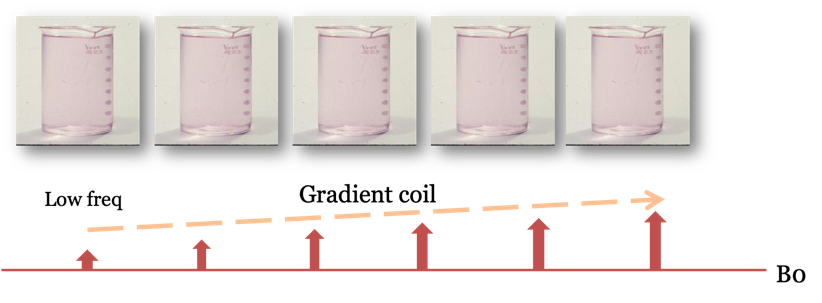

All the beakers are the same.  When we turn on a spatial gradient, each beaker, each will produce a harmonic (sinusoid) at a slightly different frequency.  We are going to imagine that we read the signals over a brief period of time, so that the sinusoid is essentially constant while we read out the signal. 

Here are a set of harmonics at different frequencies. 

**Question:**  Can you tell which signals come from the right side of the image above?

Let's suppose there are about 30 beakers

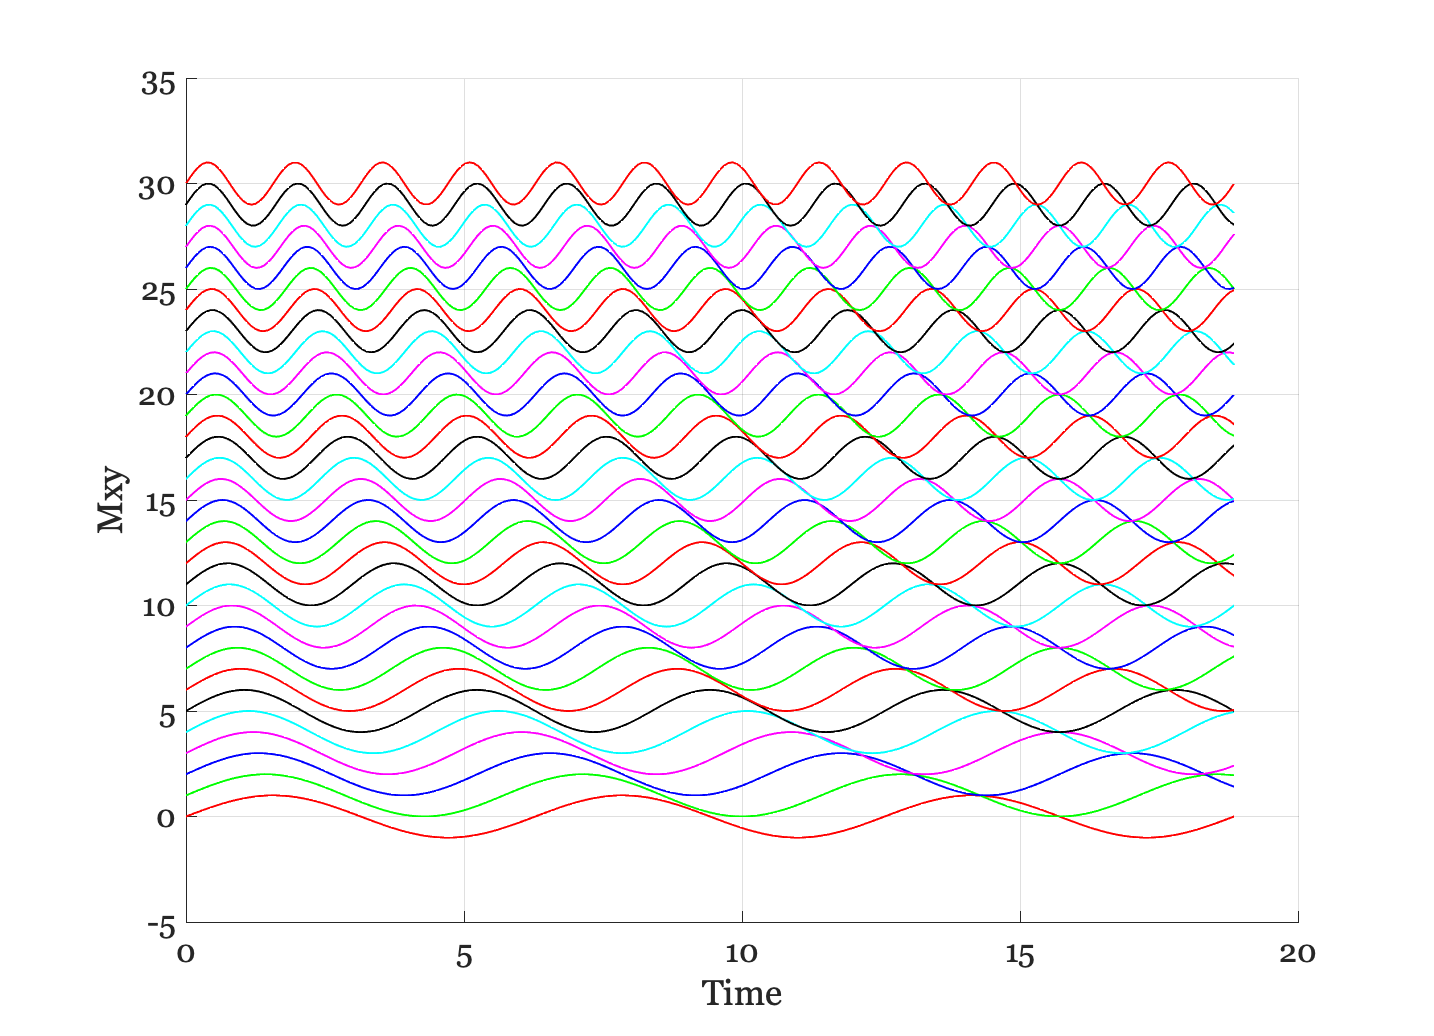

f = (1:.1:4);                 % The Larmor frequency ranges from 1 to 4 Hz
t = (0:255)/255 * 2*pi*3;     % Time points we sample are over 6*pi
sig = zeros(numel(f),numel(t));
for ii=1:numel(f)
    sig(ii,:) = sin(t*f(ii));
end

% Remember that the times run from 0 to 6*pi, which is about 18.
mrvNewGraphWin;
hold on
for ii=1:numel(f)
    plot(t,sig(ii,:)+(ii-1));
end
grid on; xlabel('Time'); ylabel('Mxy');

## Consider the signal across space

Let's pick a point in time, say 35 time steps in.  What will the amplitude of the harmonic be for each of the 31 beakers?  At the first time point, the amplitude over space looks like this.

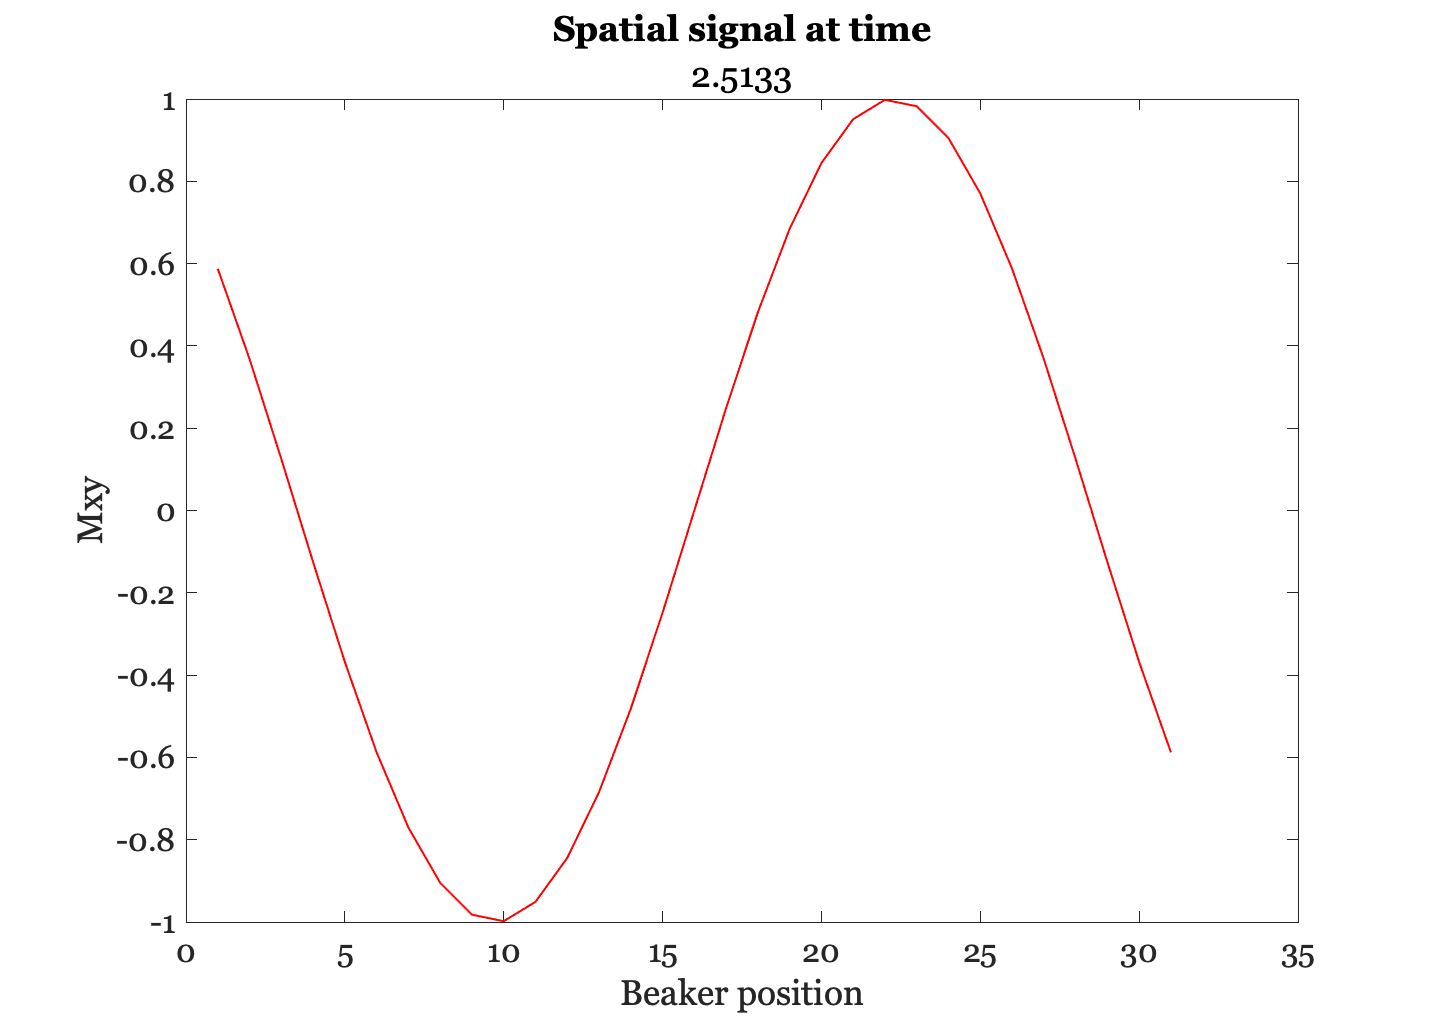

mrvNewGraphWin;

thisT = 35;
plot(sig(:,thisT));
xlabel('Beaker position'); ylabel('Mxy');
grid on;
title('Spatial signal at time',t(thisT));

Now a little later in time

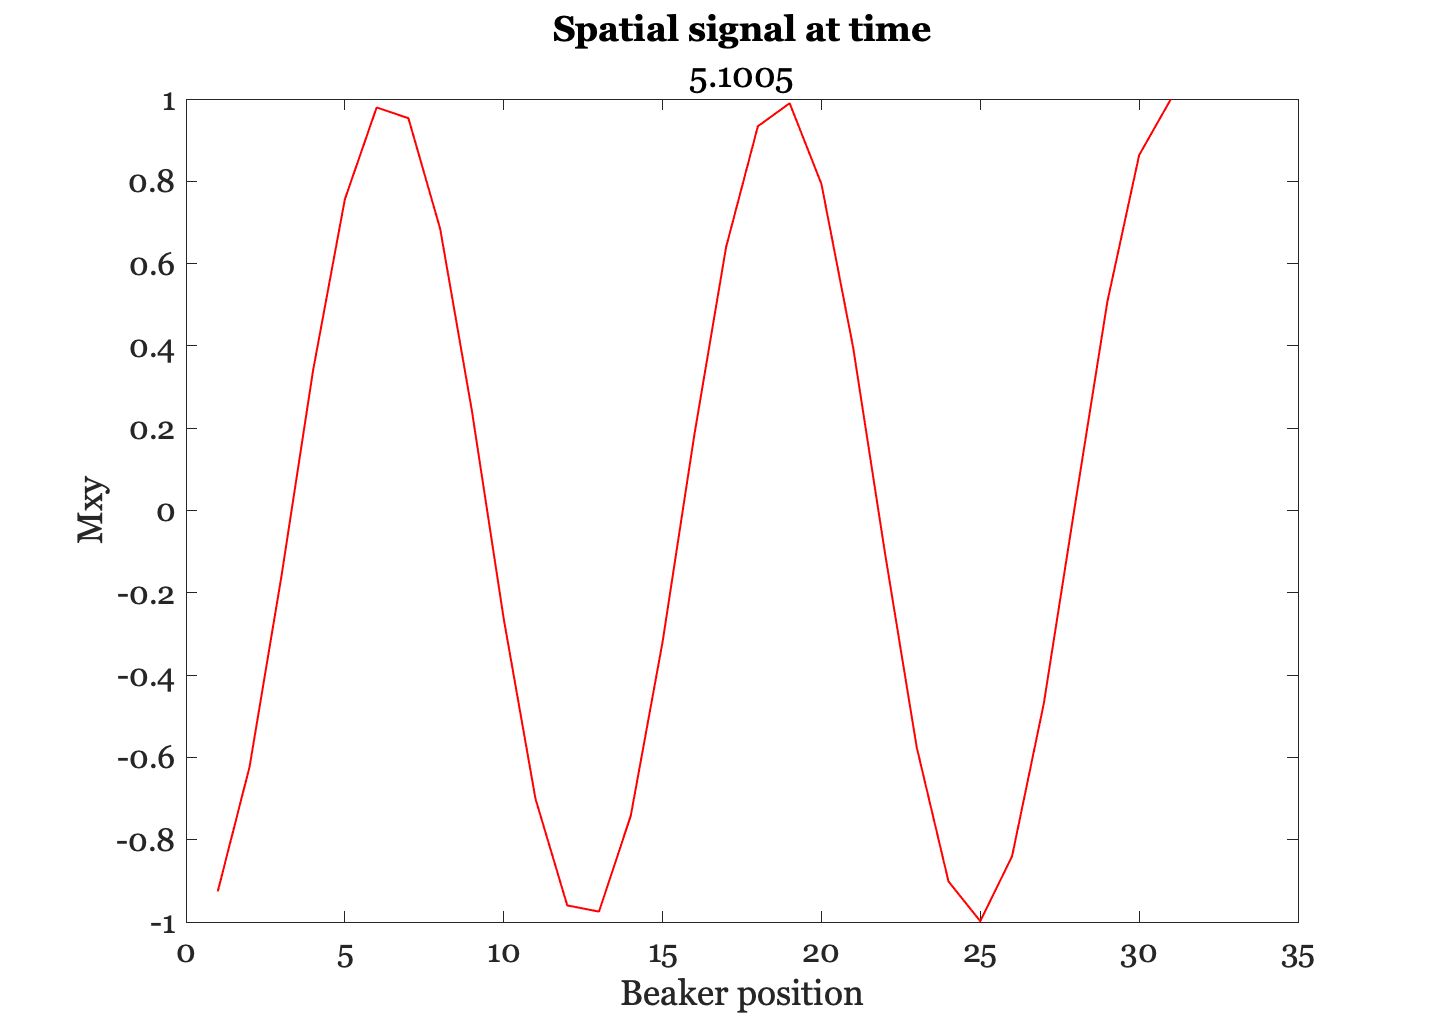

thisT = 70;
plot(sig(:,thisT));
xlabel('Beaker position'); ylabel('Mxy'); grid on;
title('Spatial signal at time',t(thisT));

And later still

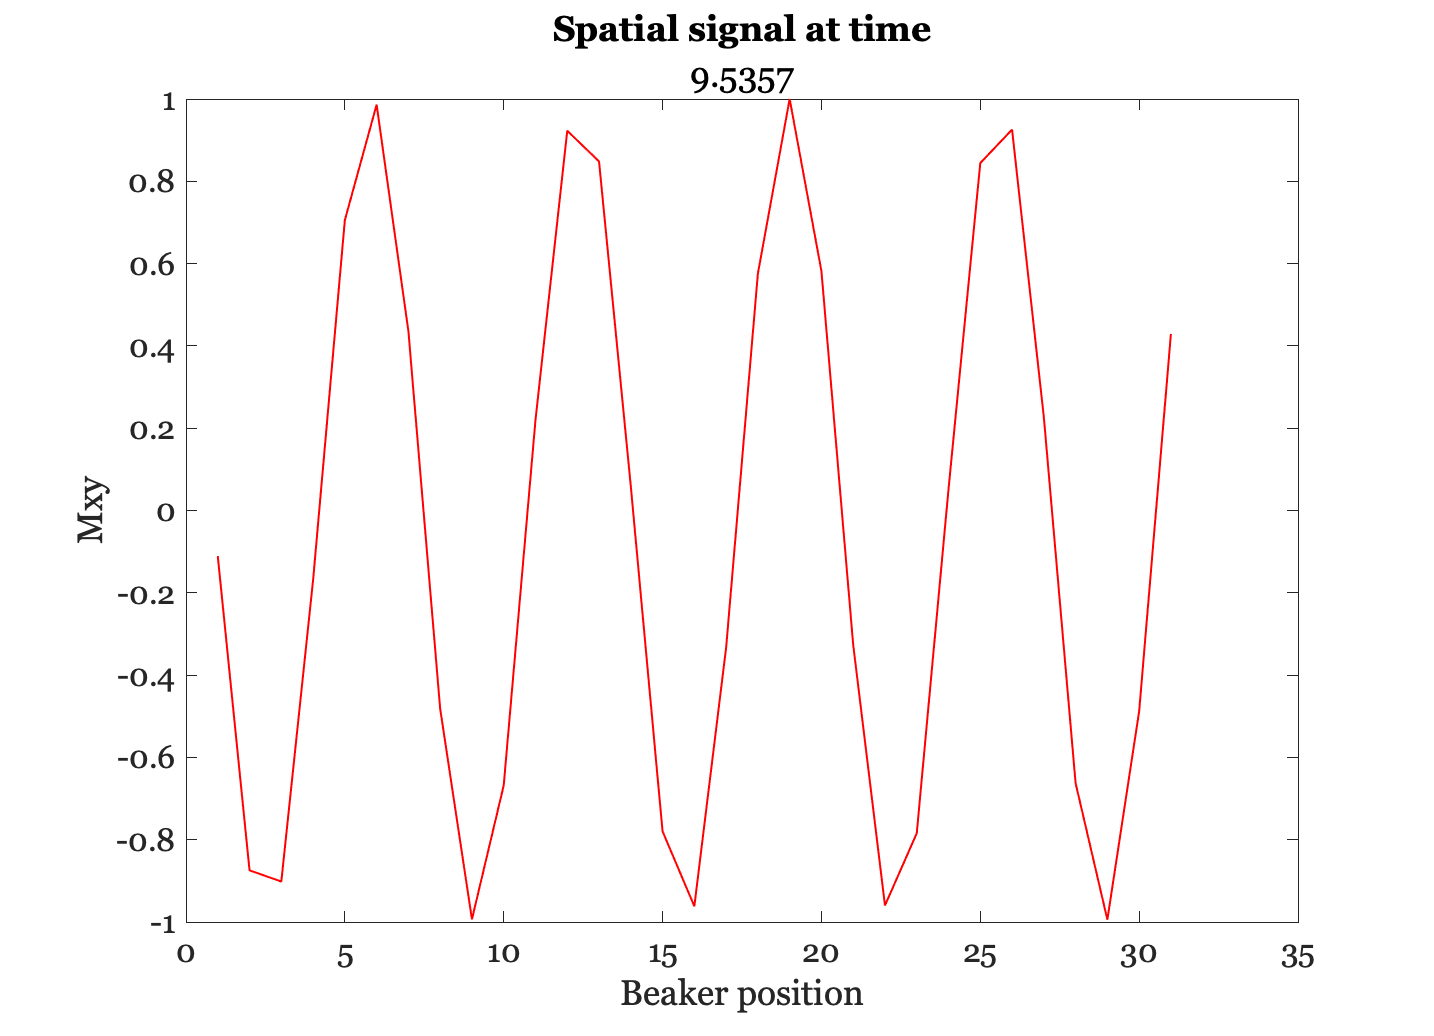

thisT = 130;
plot(sig(:,thisT));
xlabel('Beaker position'); ylabel('Mxy'); grid on;
title('Spatial signal at time',t(thisT));

At each moment in time, the spatial distribution of signals is a sinusoid.  Over time, as the signals evolve, the **spatial harmonic** that weights how much each beaker contributes has a higher and higher frequency!  (Remember, the temporal frequency of each of the beakers is constant throughout this period when we will make the measurement.).   Writing this as a simple formula, we would say  the spatial frequency changes over time

  
$$sin(2\pi (f t) x )$$
 

Next, suppose each beaker is a little bit different. In that case, the amplitude of the transverse signal may vary from beaker to beaker. I colored the beakers and changed their heights to suggest that we can scale the signal from each beaker by some amount that depends on the material in the beaker.

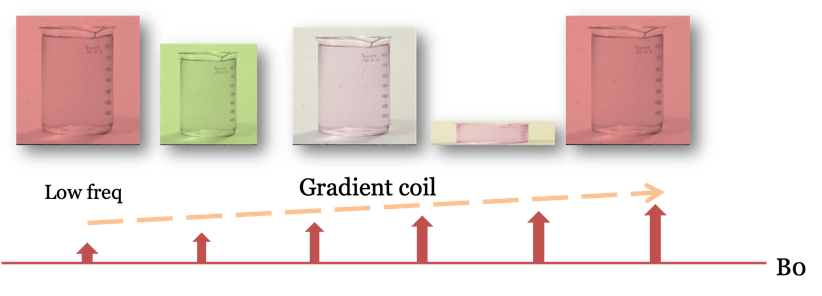

Suppose we call the variation in the intensity over space, due to the tissue properties, $T(x)$.  At each moment in time, we measure the amplitude of the tissue at $x$ weighted by the changing spatial harmonic introduced by the gradient


$$M_{xy}(t) = T(x) .* sin(2 \pi (ft) x)$$


Remember all that stuff about the Fourier Series?  Each of these values at a time $t$ looks like one of the terms in a Fourier Series! 

We could go for a more precise version of the mathematics, but for this class I think we have gone far enough.  I hope I have made it believable that at each moment in time the voltage signal is a measure of the tissue property over space $T(x)$ multipled by a harmonic over space $sin(2 \pi (ft) x)$.  Which harmonic changes over time. With a little mathematics (in fact with an appropriate Fourier Transform), we can analyze the voltage over time, $M_{xy}(t)$ and recover $T(x)$.